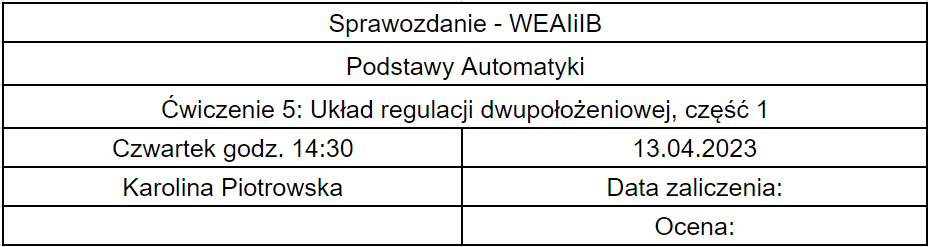

## Cel ćwiczenia

Ćwiczenie miało na celu zapoznanie z zasadami działania i właściwościami układu regulacji dwupołożeniowej.

## Wstęp teoretyczny

Rozważamy zamknięty układ regulacji składający się z obiektu regulacji opisanego poniższymi transmitancjami z opóźnieniem:

- 
$$G_{1}(s) = \frac{e^{-\tau_{1}s}}{T_{1}s+1}$$


- 
$$G_{2}(s) = \frac{e^{-\tau_{2}s}}{T_{2}s}$$


$T_{1}$ - stała czasowa, $T_{2}$ - czas całkowania, $\tau$ - stała czasowa.

## Przebieg laboratorium

SP = 0.5;
tau = 22;
T = 45;
h = 0.05;

### Statyczny obiekt regulacji

#### Wpływ szerokości histerezy regulatora

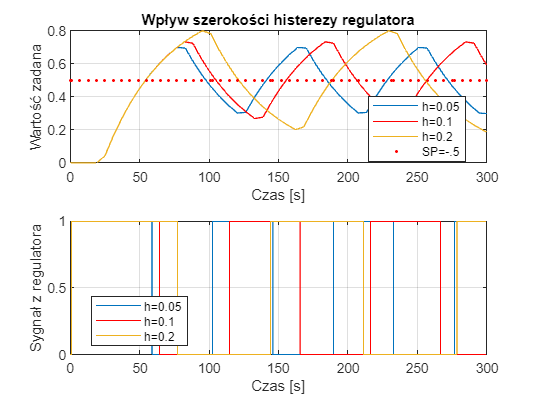

out1 = sim('lab5_sim.slx');
y1 = out1.y;
u1 = out1.u;

h = 0.1;
out2 = sim('lab5_sim.slx');
y2 = out2.y;
u2 = out2.u;

h = 0.2;
out3 = sim('lab5_sim.slx');
y3 = out3.y;
u3 = out3.u;

figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', ...
    y3.time, y3.signals.values, y1.time, SP, 'r.')
title('Wpływ szerokości histerezy regulatora')
legend('h=0.05', 'h=0.1', 'h=0.2', 'SP=-.5', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Wartość zadana')
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', ...
    u3.time, u3.signals.values)
legend('h=0.05', 'h=0.1', 'h=0.2', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Sygnał z regulatora')

#### Wpływ wartości opóźnienia obiektu

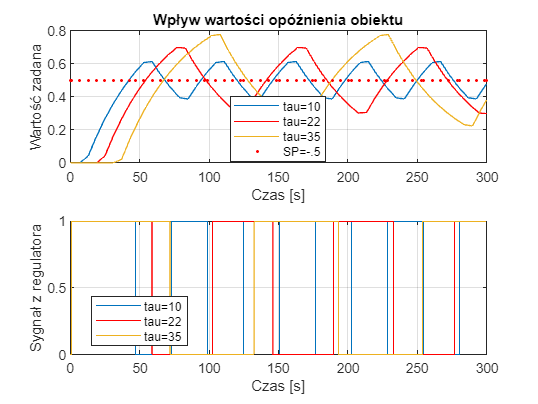

h = 0.05;
tau = 10;
out1 = sim('lab5_sim.slx');
y1 = out1.y;
u1 = out1.u;

tau = 22;
out2 = sim('lab5_sim.slx');
y2 = out2.y;
u2 = out2.u;

tau = 35;
out3 = sim('lab5_sim.slx');
y3 = out3.y;
u3 = out3.u;

figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', ...
    y3.time, y3.signals.values, y1.time, SP, 'r.')
title('Wpływ wartości opóźnienia obiektu')
legend('tau=10', 'tau=22', 'tau=35', 'SP=-.5', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Wartość zadana')
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', ...
    u3.time, u3.signals.values)
legend('tau=10', 'tau=22', 'tau=35', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Sygnał z regulatora')

#### Wpływ wartości stałej czasowej obiektu

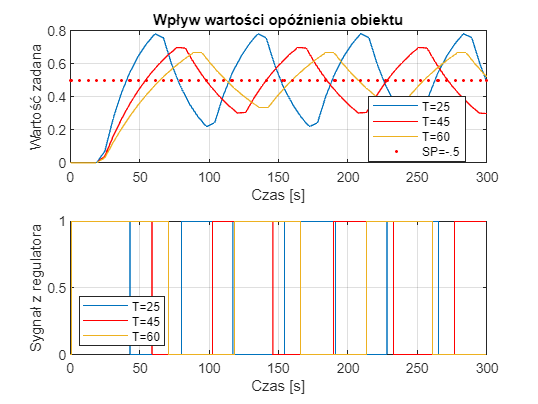

tau = 22;
T = 25;
out1 = sim('lab5_sim.slx');
y1 = out1.y;
u1 = out1.u;

T = 45;
out2 = sim('lab5_sim.slx');
y2 = out2.y;
u2 = out2.u;

T = 60;
out3 = sim('lab5_sim.slx');
y3 = out3.y;
u3 = out3.u;
figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', ...
    y3.time, y3.signals.values, y1.time, SP, 'r.')
title('Wpływ wartości opóźnienia obiektu')
legend('T=25', 'T=45', 'T=60', 'SP=-.5', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Wartość zadana')
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', ...
    u3.time, u3.signals.values)
legend('T=25', 'T=45', 'T=60', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Sygnał z regulatora')

#### Wpływ wartości zadanej

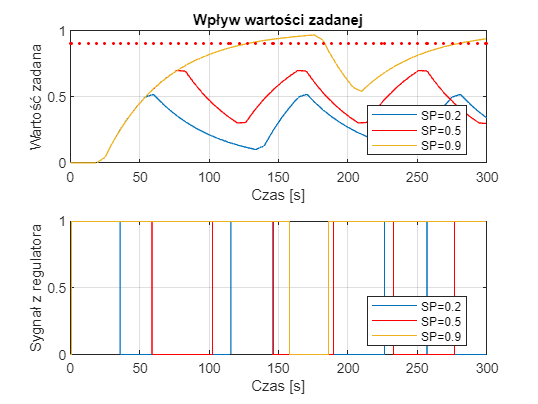

T = 45;
SP = 0.2;
out1 = sim('lab5_sim.slx');
y1 = out1.y;
u1 = out1.u;

SP = 0.5;
out2 = sim('lab5_sim.slx');
y2 = out2.y;
u2 = out2.u;

SP = 0.9;
out3 = sim('lab5_sim.slx');
y3 = out3.y;
u3 = out3.u;
figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', ...
    y3.time, y3.signals.values, y1.time, SP, 'r.')
title('Wpływ wartości zadanej')
legend('SP=0.2', 'SP=0.5', 'SP=0.9', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Wartość zadana')
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', ...
    u3.time, u3.signals.values)
legend('SP=0.2', 'SP=0.5', 'SP=0.9', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Sygnał z regulatora')

### Obiekt astatyczny

#### Wpływ wartości zadanej

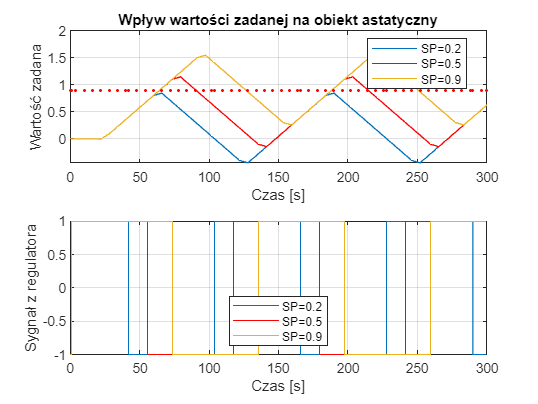

SP = 0.2;
out1 = sim('lab5_sim.slx');
y1 = out1.y;
u1 = out1.u;

SP = 0.5;
out2 = sim('lab5_sim.slx');
y2 = out2.y;
u2 = out2.u;

SP = 0.9;
out3 = sim('lab5_sim.slx');
y3 = out3.y;
u3 = out3.u;
figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', ...
    y3.time, y3.signals.values, y1.time, SP, 'r.')
title('Wpływ wartości zadanej na obiekt astatyczny')
legend('SP=0.2', 'SP=0.5', 'SP=0.9', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Wartość zadana')
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', ...
    u3.time, u3.signals.values)
legend('SP=0.2', 'SP=0.5', 'SP=0.9', 'Location', 'best')
grid on
xlabel('Czas [s]')
ylabel('Sygnał z regulatora')

## Wnioski

Ćwiczenie pozwoliło dobrze zapoznać się z układem regulacji dwupołożeniowej.

Wraz ze wzrostem szerokości histerezy rosły okresy sygnałów z regulatora i wyjściowego; rosły także amplitudy tych sygnałów.

Przy zwiększającym się opóźnieniu układu osiągał większe wartości zadane; dla małych opóźnień sygnał wyjściowy oscylował z większą częstotliwością.

Wraz ze wzrostem stałej czasowej częstotliwość i amplitudqa oscylacji malały.

Wraz ze wzrostem wartości zadanej wydłuża się czas narastania. Dla najmniejszej wartości zadanej wartość średnia sygnału wyjściowego jest najbliższa wartości zadanej.

Przy obiekcie astatycznym pierwsze włączenie regulatora następuje później wraz ze wzrostem wartości zadanej. 